clear;
clc;
run = load("20SStableRun.mat");

dy = timeseries2timetable(run.data{9}.Values.dy);
y = timeseries2timetable(run.data{9}.Values.y);

dx = timeseries2timetable(run.data{9}.Values.dx);

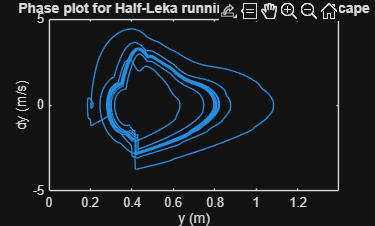

% Final plots
plot(y.y,dy.dy);
hold on
xlabel("y (m)")
ylabel("dy (m/s)")
title("Phase plot for Half-Leka running control in Simscape")
axis([0 1.4 -5 5])
hold off

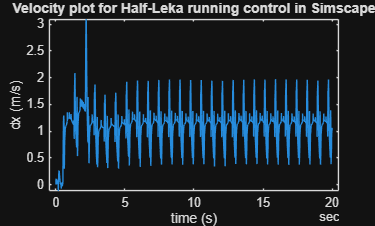


plot(dx.Time, dx.dx)
hold on
xlabel("time (s)")
ylabel("dx (m/s)")
title("Velocity plot for Half-Leka running control in Simscape")
hold off